Open the dataset

close all; clear; clc

train = readtable("train.csv");

Class and survival rate

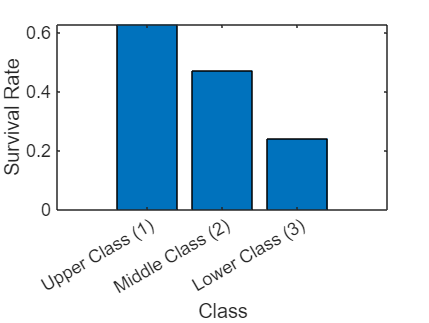

% Initialize the variables
survived  = table2array(train(:,"Survived"));
Pclass = table2array(train(:,"Pclass"));
class = unique(Pclass);
survivalRates = zeros(length(class), 1);

% Assign a survival rate for a particular class
for i = 1:length(class)
    selectedClass = class(i);
    idx = Pclass == selectedClass; % index where the Pclass matches the selectedClass
    survivalRates(i) = sum(survived(idx)) / sum(idx);
end

% Plot
bar(class, survivalRates)
xlabel('Class');
ylabel('Survival Rate');
xticks(class);
xticklabels({'Upper Class (1)', 'Middle Class (2)', 'Lower Class (3)'});

Titles and survival rate

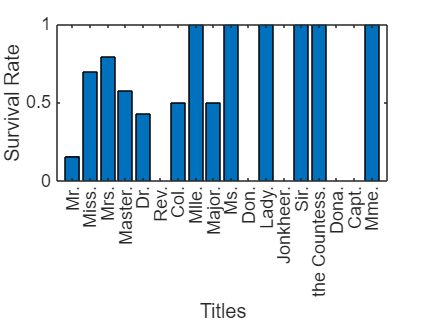

% Initialize the variables
name = table2array(train(:,"Name"));
titles = {'Mr.','Miss.', 'Mrs.', 'Master.', 'Dr.','Rev.', 'Col.', 'Mlle.', 'Major.', 'Ms.', 'Don.', 'Lady.', ...
         'Jonkheer.', 'Sir.', 'the Countess.', 'Dona.', 'Capt.', 'Mme.'};
title_and_survival = cell(length(titles), 4); % column 1 is title name; column 2 is title count; column 3 is title survived; and column 4 is title survival rate.

% Make the number of titles, survived, and survival rate equal to 0 first
for i = 1:length(titles)
    title_and_survival{i, 2} = 0;
    title_and_survival{i, 3} = 0;
    title_and_survival{i, 4} = 0;
end

% If name has title add it to the appropriate title. In addition, add to the survival count of the title if they survive.
for i = 1:length(name)
    for j = 1:length(titles)
        if contains(name(i), titles{j});
            title_and_survival{j, 1} = titles{j};
            title_and_survival{j, 2} = title_and_survival{j, 2} + 1;
            if (survived(i) == 1)
                title_and_survival{j, 3} = title_and_survival{j, 3} + 1;
            end
        end
    end
end

% Assign a survival rate for a particular title
for i = 1:length(titles)
    title_and_survival{i,4} = title_and_survival{i,3} / title_and_survival{i,2};
end
survivalRates = cell2mat(title_and_survival(:,4));

% Plot
bar(titles, survivalRates(:))
xlabel('Titles');
ylabel('Survival Rate');
xticks(titles);

First character or deck of cabin

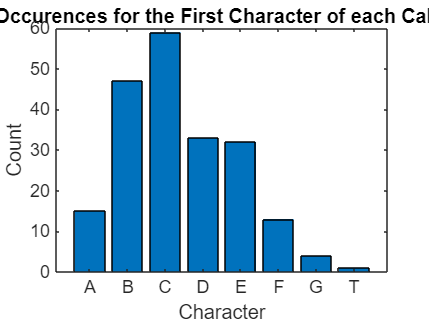

% Initialize the variables
cabin = table2array(train(:,"Cabin"));
cabin = cabin(~cellfun('isempty',cabin))';
firstCharacters = cellfun(@(x) x(1), cabin);

% Count the number of each unique first character of the cabin
uniqueChars = unique(firstCharacters);
charCounts = histc(firstCharacters, uniqueChars);
uniqueChars = cellstr(uniqueChars);
uniqueChars = cellfun(@(x) num2cell(x(:)'), uniqueChars, 'UniformOutput', false);

% Create a bar plot
bar(uniqueChars{1,1}, charCounts);
xlabel('Character');
ylabel('Count');
title('Count of Occurences for the First Character of each Cabin Number');

Null count of cabin

cabin = table2array(train(:,"Cabin"));
cabinNullCount = sum(cellfun(@isempty, cabin))

cabinNullCount = 687

Fare distribution

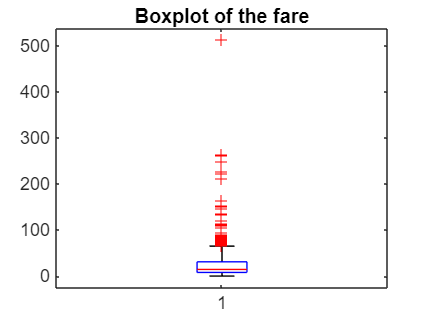

% Initialize the variables
fare = table2array(train(:,"Fare"));

% Plot the fare to illustrate the severity of outliers
boxplot(fare);
title('Boxplot of the fare');

Survival and fare

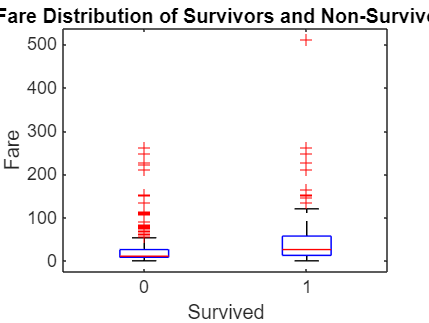

% Initialize the variables
fare = table2array(train(:,"Fare"));
survived  = table2array(train(:,"Survived"));

% Plot
boxplot(fare,survived);
xlabel('Survived')
ylabel('Fare');
title('Fare Distribution of Survivors and Non-Survivors');

Null count of age

age = table2array(train(:,"Age"));
ageNullCount = sum(isnan(age))

ageNullCount = 177

Survival, age, and gender

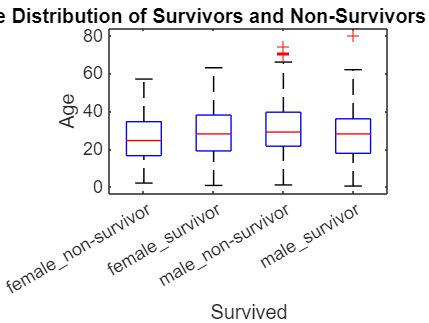

% Initialize the variables
age = table2array(train(:,"Age"));
sex = table2array(train(:,"Sex"));
survived  = table2array(train(:,"Survived"));

% Replace 0 and 1 with survived and Died
survived_string = cell(size(survived));
survived_string(survived == 0) = {'non-survivor'};
survived_string(survived == 1) = {'survivor'};

% Group and Plot
groups = strcat(sex, '_', survived_string);
groupLabels = categorical(groups);
boxplot(age,groupLabels);
ylabel('Age');
xlabel('Survived')
title('Age Distribution of Survivors and Non-Survivors by Gender');

Age distribution

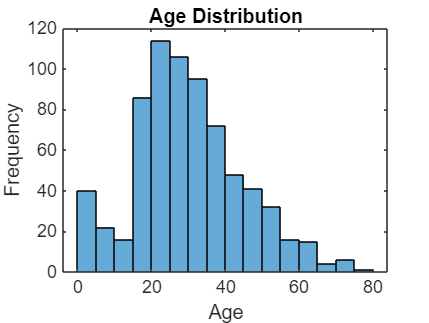

% Initialize the numbers
age = table2array(train(:,"Age"));

% Plot
histogram(age);
xlabel('Age');
ylabel('Frequency')
title('Age Distribution');